# MSc Project IIS1 | BWFLnet_Water Analysis

#### Prepared by: Yuanfei Wang

#### Date: 17 July 2022

clc
clear
close all

### Model Setup and Initialisation

Initialisation of EPANET Matlab toolkit and loading of .net file.

epanet_path = 'E:\Program Files\MATLAB\R2021b\toolbox\epanet\EPANET-Matlab-Toolkit-master';
net_id = 'BWFLnet_MSc_2022_calibrated';
run( [epanet_path,'\start_toolkit'])

EPANET-MATLAB Toolkit Paths Loaded.


net = epanet([net_id,'.inp']);

EPANET version {20200} loaded (EMT version {v2.2.0}).
Loading File "BWFLnet_MSc_2022_calibrated.inp"...
Input File "BWFLnet_MSc_2022_calibrated.inp" loaded sucessfuly.


load("wq_data.mat");
load("R_CData.mat");

### Network Data Loading

Load general network data, noting that this network has already been hydraulically calibrated, thus we can directly perform the quality analysis.

% Save element count variables
nn = net.NodeJunctionCount;
n0 = net.NodeReservoirCount;
np = net.LinkCount; % count of pipes and valves
D = net.getLinkDiameter';
R = net.getLinkRoughnessCoeff';

% Save node and link index vectors
Reservoir_Idx = net.getNodeReservoirIndex;
Junction_Idx = net.getNodeJunctionIndex;
Link_Idx = double(net.getLinkIndex);

% Specify hydraulic and quality time steps (in seconds)
net.setTimeQualityStep(15*60); % 15 minute quality time steps
net.setTimeHydraulicStep(15*60); % 15 minute hydraulic time steps
nt = net.getTimeSimulationDuration./3600; % number of time steps in hours
days = 7; % simulation duration in days
net.setTimeSimulationDuration(nt*3600*days/7); % Set the simulation duration by changing days
nt = net.getTimeSimulationDuration./3600; % get the new nt


### Graph Creation Preparation

Use graph theory to plot network connectivity and spatial coordinates.

% Create A12 and A10 incidence matrices
LinkNodesList = net.getLinkNodesIndex;

A = zeros(np,nn+n0);
for k=1:np
    i = LinkNodesList(k,1);
    j = LinkNodesList(k,2);
    A(k,i) = -1;
    A(k,j) = 1;
end

A12 = A(:,Junction_Idx);
A10 = A(:,Reservoir_Idx);
A12 = sparse(A12);
A10 = sparse(A10);

% Obstain node XY and elevation information
XY = zeros(nn+n0,2);
XY(:,1) = net.getNodeCoordinates{1};
XY(:,2) = net.getNodeCoordinates{2};
elev = double(net.getNodeElevations(Junction_Idx))';

% Create adjacency matrix
A = [A12,A10];
AdjA = sparse(size(A,2),size(A,2));

for k = 1:size(A,1)
    node_in = find(A(k,:) == -1);
    node_out = find(A(k,:) == 1);
    AdjA(node_in,node_out) = 1;
    AdjA(node_out,node_in) = 1;
end
gr = graph(AdjA);

### Chlorine Simulation

Setup general chemical simulation parameters.

% Initialise EPANET simulation type
net.setQualityType('Chemical','mg/L');
net.setNodeSourceQuality(1:nn+n0,zeros(nn+n0,1)); % set all node source quality to zero

% Load the water quality data
Junction_SelectIdx = net.getNodeIndex(wq_data.node_ids);
Junction_SelectIdx = Junction_SelectIdx([1,4,7,9]);
Junction_HydrantIdx = net.getNodeIndex(wq_data.node_ids([2,5,8]));
cext = wq_data.chlorine([3,6],:);

Assign chlorine decay parameters.

% Link bulk reaction coefficients
lambda = 0.82*ones(np,1); % units of days^-1
net.setLinkBulkReactionCoeff(1:np, -lambda);
net.setOptionsPipeBulkReactionOrder(1);

% Link wall decay reaction coefficients... apply by pipe size for S&G?
% theta = ones(np,1); % units of m/day
% for k = 1:np
%     if D(k) <= 75
%         theta(k) = 0.25;
%     elseif D(k) > 75 && D(k) <= 150
%         theta(k) = 0.175;
%     elseif D(k) > 150 && D(k) <= 250
%         theta(k) = 0.1;
%     else
%         theta(k) = 0.05;
%     end
% end
% 
% net.setLinkWallReactionCoeff(1:np, -theta);
% net.setOptionsPipeWallReactionOrder(1);

% Initial concentrations at nodes (mg/L)
c0 = zeros(nn+n0,nt);
net.setNodeInitialQuality(net.NodeIndex,c0);

% % Assign source chlorine with time varying pattern
% cext = ones(n0,nt);
% 
% % Constant source concentration for n0 reservoirs
% % cext = cext*0.25;
% 
% % Varying source concentration by source element
% source_c = [1.00, 0.85];

% for j = 1:n0
%     cext(j,:) = source_c(j)*cext(j,:);
% end

% Varying source concentration by source element with
% concentration spike (pulse) at t = 12
% t = 144;
% for i = 1:4*days*nt
%     for j = 1:n0
%         if i == t
%             cext(j,i) = 1*cext(j,i); % Pulse of 1 mg/L
%         else
%             cext(j,i) = source_c(j)*cext(j,i);
%         end
%     end
% end

base_cext = ones(n0,1); 
pattern_cext = cext./(base_cext*ones(1,size(cext,2))); % extend vector over nt columns 

% For loop to assign new patterns to source contrations at reservoirs and
% source type
for i=1:n0
    patternId = sprintf('Res_C_%d',i);
    net.addPattern(patternId,pattern_cext(i,:));
    net.setNodeSourcePatternIndex(net.NodeReservoirIndex(i),net.getPatternIndex(patternId));
    net.setNodeSourceQuality(net.NodeReservoirIndex(i),base_cext(i));
    net.setNodeSourceType(net.NodeReservoirIndex(i),'CONCEN');  
end

### Results from EPANET Simulation

Simulate hydraulic and quality analyses using EPANET's solvers.

hydraulic_res = net.getComputedHydraulicTimeSeries;
quality_res = net.getComputedQualityTimeSeries;

% Assign hydraulic results to network elements
h = hydraulic_res.Head(1:1+4*nt,1:nn).';
q = 1e-3*hydraulic_res.Flow(1:1+4*nt,:).';

% Assign quality results to network elements
c_nodes = quality_res.NodeQuality';
c_pipes = quality_res.LinkQuality';

### Genetic Algorithm Preparation

Implement genetic algoritnm to solve the parameter optimization problem.

% Get the simulated and observed data
c_nodes_Sim = c_nodes(Junction_SelectIdx,:);
c_nodes_Obs = wq_data.chlorine([1,4,7,9],:);

Plot the simulated chlorine concentration for visualisation.

% create the plot for simulated chlorine concentration
for i = 1:length(Junction_SelectIdx)
    Junction_Name{i} = sprintf('BW %d',i);
end

for i = 1:length(Junction_HydrantIdx)
    Junction_Hydrant_Name{i} = sprintf('BWH %d',i);
end


According to the water age analysis, the longest water age before periodic behaviour is approxiamately 40 hours, thus we split the data into three parts, the first part is a 2-day stabilisation period, the second part is a 1-day train data, the last part is the 4-day validation time.

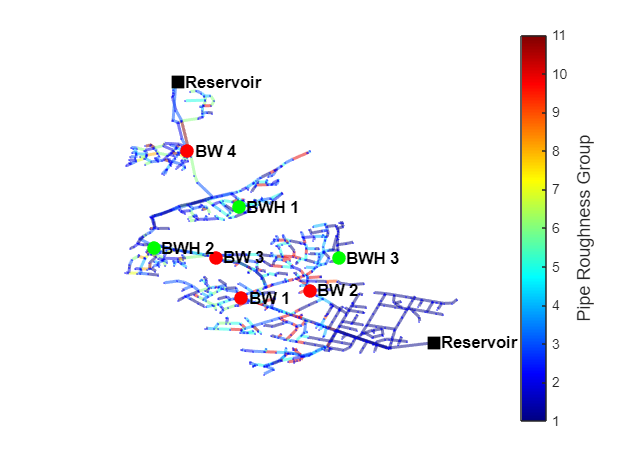

% Data splitting
c_nodes_Sim = c_nodes_Sim(:,2:end);
Sim_train = c_nodes_Sim(:,2*96+1:3*96);
Sim_val = c_nodes_Sim(:,3*96+1:end);
Obs_train = c_nodes_Obs(:,2*96+1:3*96);
Obs_val = c_nodes_Obs(:,3*96+1:end);
mse_function = @(sim,obs) (1/size(obs,1)/size(obs,2))*sum(sum((sim - obs).^2));
mse_before = mse_function(Sim_val,Obs_val);

% Plot the sensor location on the network map
figure
p1 = plot(gr);
p1.XData = XY(:,1);
p1.YData = XY(:,2);
p1.LineWidth = 2;
p1.EdgeColor = 'k';
p1.MarkerSize = 1e-10;
p1.NodeColor = 'b';
p1.NodeLabel = '';
highlight(p1,Junction_SelectIdx,'NodeColor','r','MarkerSize',8);
labelnode(p1,Junction_SelectIdx,Junction_Name);
highlight(p1,Junction_HydrantIdx,'NodeColor','g','MarkerSize',8);
labelnode(p1,Junction_HydrantIdx,Junction_Hydrant_Name);
highlight(p1,Reservoir_Idx,'NodeColor','k','Marker','s','MarkerSize',10);
labelnode(p1,Reservoir_Idx,{'Reservoir','Reservoir'});
p1.NodeFontSize = 11;
p1.NodeLabelColor = 'k';
p1.NodeFontWeight = 'bold';
p1.EdgeFontSize = 11;
p1.EdgeLabelColor = 'k';
p1.EdgeFontWeight = 'bold';
p1.EdgeCData = R_CData;
hcb_R = colorbar;
colormap('jet');
hcb_R.Label.String = 'Pipe Roughness Group';
hcb_R.Label.FontSize = 12;
axis('off')

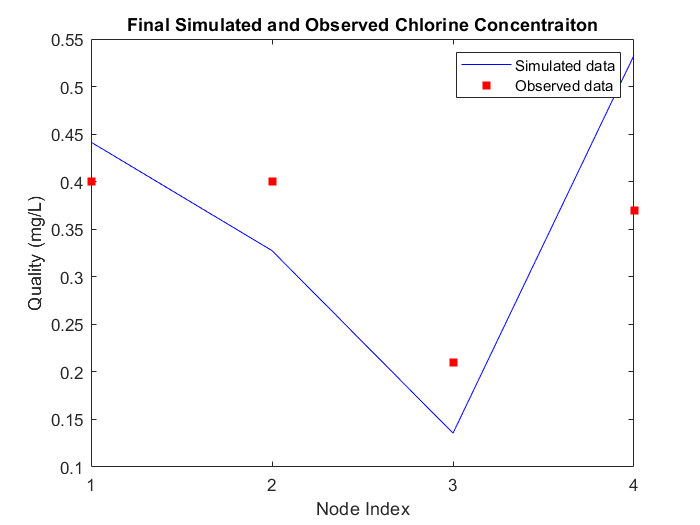

% title('Pipe Grouping and Sensor Locations in Network')
% Plot the calibrated quality-time figure
figure,
plot(1:size(c_nodes_Obs,1),Sim_train(:,end),'-b')
hold on
scatter(1:size(c_nodes_Obs,1),Obs_train(:,end),'red','filled','square')
legend({'Simulated data','Observed data'})
xlabel('Node Index')
ylabel('Quality (mg/L)')
xticks(1:1:size(c_nodes_Obs,1));
title('Final Simulated and Observed Chlorine Concentraiton')

### No Group Genetic Algorithm Implementation

Implement genetic algoritnm to solve the parameter optimization problem based on one group.

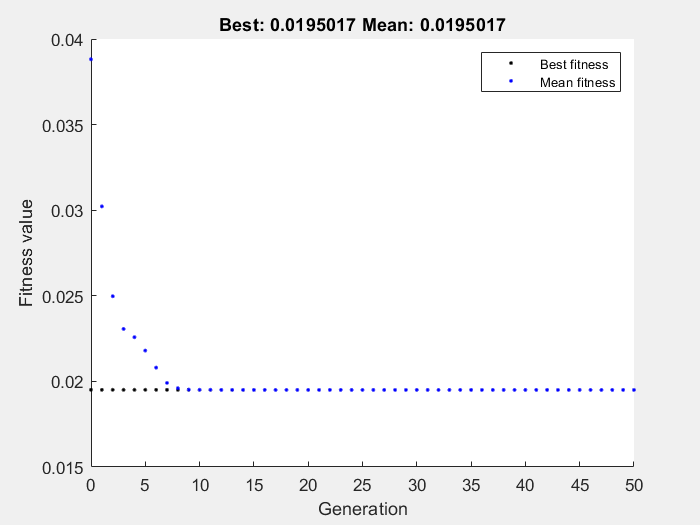

% % genetic algorithm implementation
rng default
% options = optimoptions('ga','Display','none','PopulationType','DoubleVector','PopulationSize',1,'InitialPopulation', ...
%     100,'Generations',100,"ConstraintTolerance",1e-6,"PlotFcn","gaplotbestf");
options = optimoptions('ga','Display','none','PopulationType','DoubleVector','PopulationSize',50,'InitialPopulation',50, ...
    'Generations',50,"ConstraintTolerance",1e-6,"PlotFcn","gaplotbestf");

lb = -10;
ub = 0;

tic;
Mse_function = @(x) Mse_NoGroup(x,Obs_train,Junction_SelectIdx);
[x_NoGroup, fval_NoGroup] = ga(Mse_function,1,[],[],[],[],lb,ub,[],options);

t_NoGroup = toc;
fprintf('The computation time is %.2fs',t_NoGroup);

The computation time is 515.39s

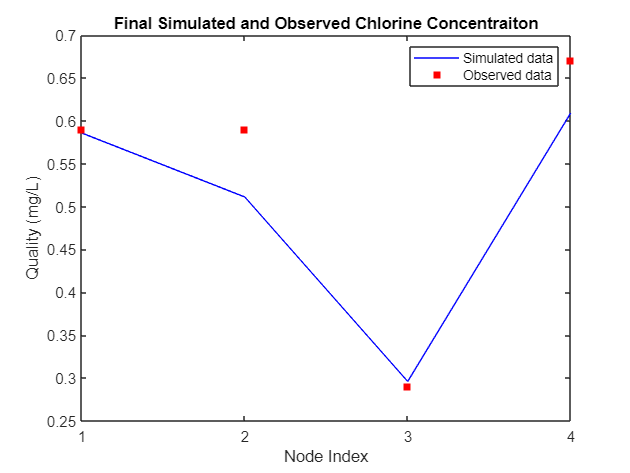

% Test the ga result
theta_NoGroup = ones(2281,1); % units of m/day
for i = 1:2281
    theta_NoGroup(i) = x_NoGroup(1);
end
net.setLinkBulkReactionCoeff(1:np, theta_NoGroup);
net.setOptionsPipeBulkReactionOrder(1);
quality_res_NoGroup = net.getComputedQualityTimeSeries;

net.getLinkBulkReactionCoeff;
c_nodes_NoGroup = quality_res_NoGroup.NodeQuality';
c_nodes_Sim_NoGroup = c_nodes_NoGroup(Junction_SelectIdx,2:end);
Sim_NoGroup_val = c_nodes_Sim_NoGroup(:,3*96+1:end);
mse_after_NoGroup = mse_function(Sim_NoGroup_val,Obs_val);

% Plot the ga-modified quality-time figure
figure,
plot(1:size(c_nodes_Obs,1),Sim_NoGroup_val(:,end),'-b')
hold on
scatter(1:size(c_nodes_Obs,1),Obs_val(:,end),'red','filled','square')
legend({'Simulated data','Observed data'})
xlabel('Node Index')
ylabel('Quality (mg/L)')
xticks(1:1:size(c_nodes_Obs,1));
title('Final Simulated and Observed Chlorine Concentraiton')

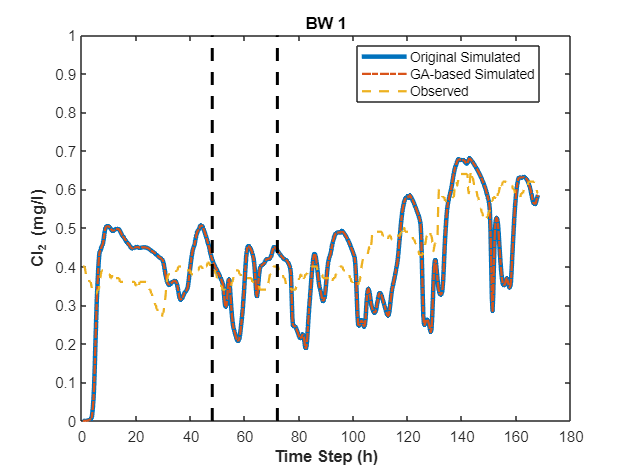

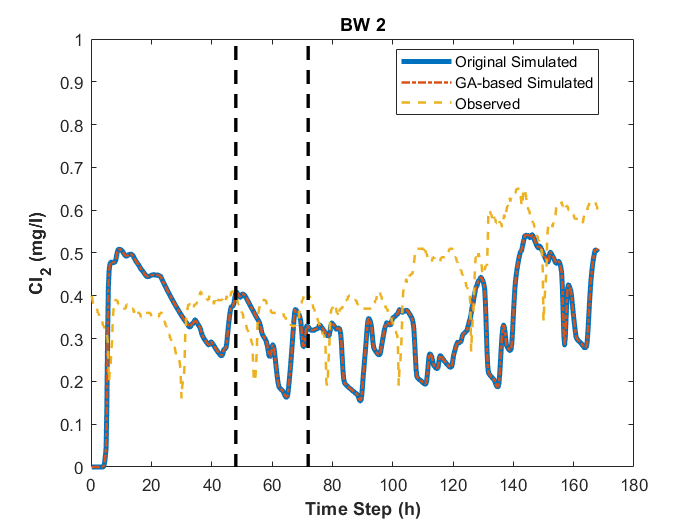

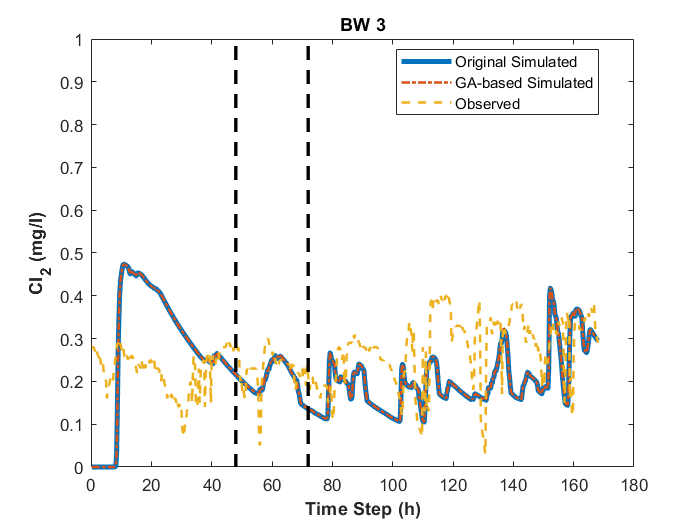

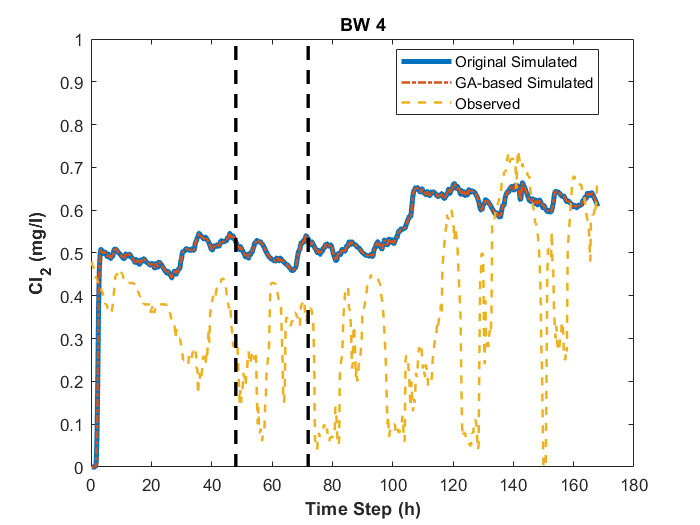

% figures for simulated and observed data
for i = 1:size(c_nodes_Obs,1)
    figure,
    plot(0.25:0.25:days*24,c_nodes_Sim(i,:),'-','LineWidth',3)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Sim_NoGroup(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Obs(i,:),'LineStyle','--','LineWidth',1.5)
    hold on
    plot([48,48],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    hold on
    plot([72,72],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    legend({'Trial-and-Error Simulated','GA-based Simulated','Observed'},'location','best');
    xlabel('Time Step (h)','fontweight','bold')
    ylabel('Cl_2 (mg/l)','fontweight','bold')
    title(Junction_Name{i})
end


fprintf('The mse before calibration is %.4f, after calibration it is %.4f',mse_before,mse_after_NoGroup);

The mse before calibration is 0.0386, after calibration it is 0.0385

### Diameter based Group Genetic Algorithm Implementation

Implement genetic algoritnm to solve the parameter optimization problem based on diameter groups.

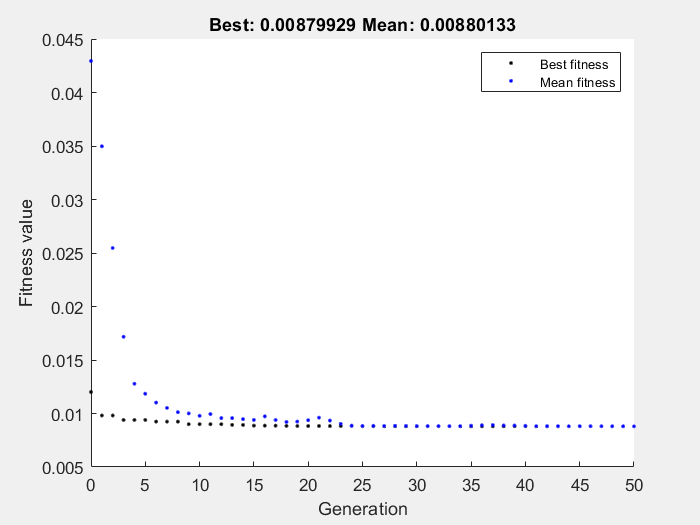

% % genetic algorithm implementation
rng default
options = optimoptions('ga','Display','none','PopulationType','DoubleVector','PopulationSize',50, ...
    'Generations',50,"ConstraintTolerance",1e-6,"PlotFcn","gaplotbestf");

lb = [-10,-10,-10,-10];
ub = [0,0,0,0];

tic;
Mse_function = @(x) Mse_D(x,Obs_train,Junction_SelectIdx,D);
[x_D, fval_D] = ga(Mse_function,4,[],[],[],[],lb,ub,[],options);

t_D = toc;
fprintf('The computation time is %.2fs',t_D);

The computation time is 520.30s


% Test the ga result
theta_D = ones(2281,1); % units of m/day
for i = 1:2281
    if D(i) <= 75
        theta_D(i) = x_D(1);
    elseif D(i) > 75 && D(i) <= 150
        theta_D(i) = x_D(2);
    elseif D(i) > 150 && D(i) <= 250
        theta_D(i) = x_D(3);
    else
        theta_D(i) = x_D(4);
    end
end
net.setLinkBulkReactionCoeff(1:np, theta_D);
net.setOptionsPipeBulkReactionOrder(1);
quality_res_D = net.getComputedQualityTimeSeries;
c_nodes_D = quality_res_D.NodeQuality';
c_nodes_Sim_D = c_nodes_D(Junction_SelectIdx,2:end);


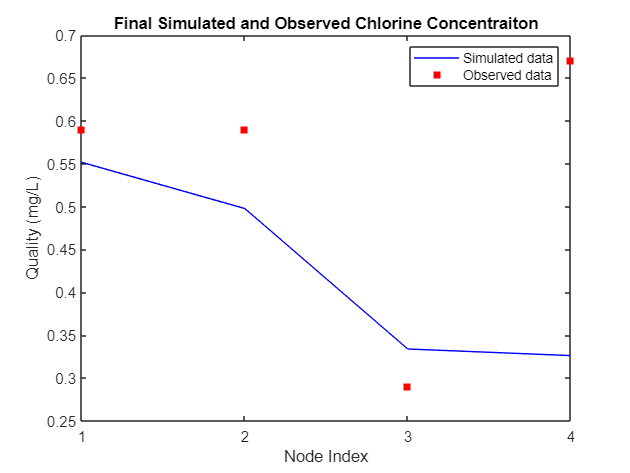

Sim_D_val = c_nodes_Sim_D(:,3*96+1:end);
mse_after_D = mse_function(Sim_D_val,Obs_val);

% Plot the ga-modified quality-time figure
figure,
plot(1:size(c_nodes_Obs,1),Sim_D_val(:,end),'-b')
hold on
scatter(1:size(c_nodes_Obs,1),Obs_val(:,end),'red','filled','square')
legend({'Simulated data','Observed data'})
xlabel('Node Index')
ylabel('Quality (mg/L)')
xticks(1:1:size(c_nodes_Obs,1));
title('Final Simulated and Observed Chlorine Concentraiton')

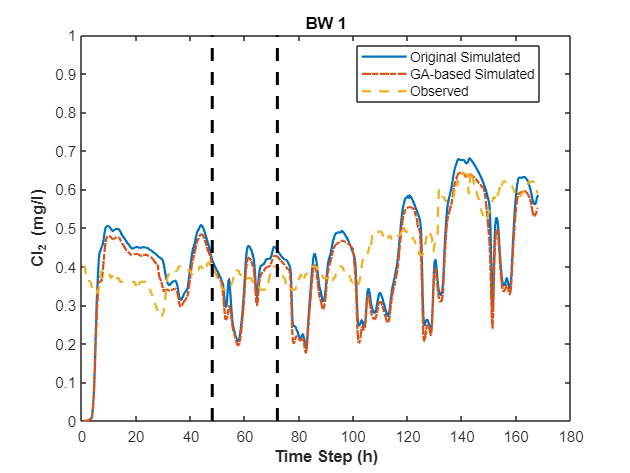

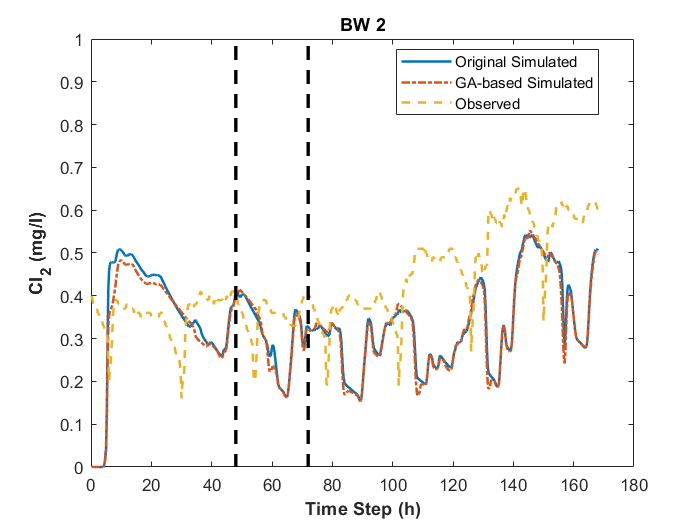

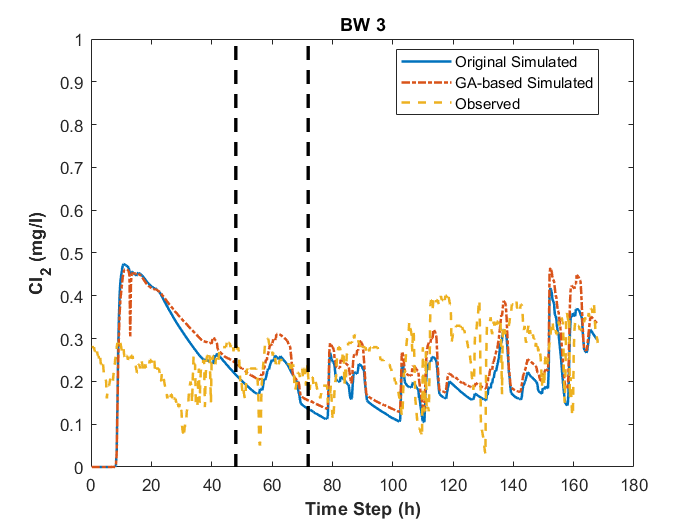

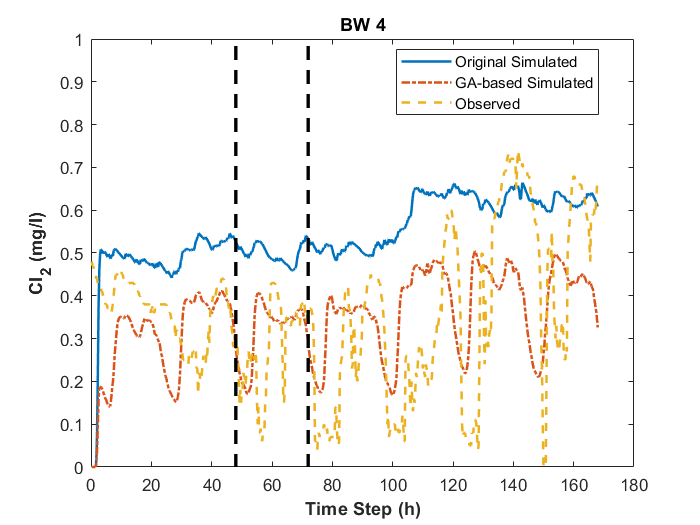

% figures for simulated and observed data
for i = 1:size(c_nodes_Obs,1)
    figure,
    plot(0.25:0.25:days*24,c_nodes_Sim(i,:),'-','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Sim_D(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Obs(i,:),'LineStyle','--','LineWidth',1.5)
    hold on
    plot([48,48],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    hold on
    plot([72,72],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    legend({'Trial-and-Error Simulated','GA-based Simulated','Observed'},'location','best');
    xlabel('Time Step (h)','fontweight','bold')
    ylabel('Cl_2 (mg/l)','fontweight','bold')
    title(Junction_Name{i})
end


fprintf('The mse before calibration is %.4f, after calibration it is %.4f',mse_before,mse_after_D);

The mse before calibration is 0.0386, after calibration it is 0.0278

### Roughness based Group Genetic Algorithm Implementation

Implement genetic algoritnm to solve the parameter optimization problem based on roughness groups.

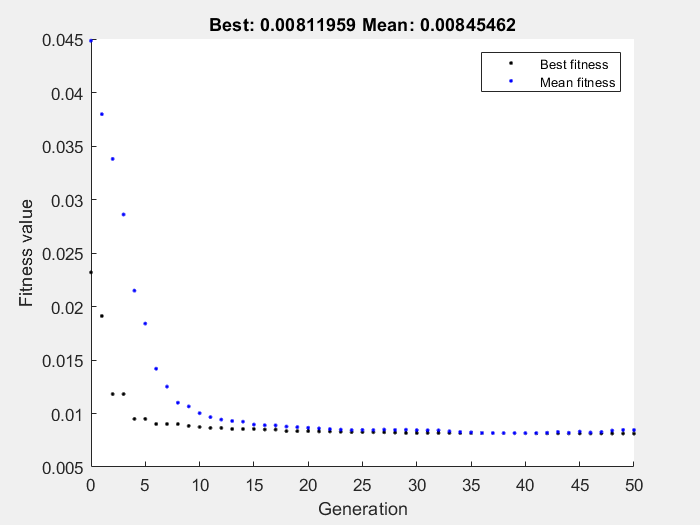

% genetic algorithm implementation
rng default
options = optimoptions('ga','Display','none','PopulationType','DoubleVector','PopulationSize',50, ...
    'Generations',50,"ConstraintTolerance",1e-6,"PlotFcn","gaplotbestf");

lb = -10*ones(11,1);
ub = 0*ones(11,1);

tic;
Mse_function = @(x) Mse_R(x,Obs_train,Junction_SelectIdx,R);
[x_R, fval_R] = ga(Mse_function,11,[],[],[],[],lb,ub,[],options);

t_R = toc;
fprintf('The computation time is %.2fs',t_R);

The computation time is 522.32s


% Test the ga result
theta_R = ones(2281,1); % units of m/day
for i = 1:2281
    if abs(R(i) - 0) <= 0.01
        theta_R(i) = x_R(1);
    elseif abs(R(i) - 0.1000) <= 0.01
        theta_R(i) = x_R(2);
    elseif abs(R(i) - 0.1399) <= 0.01
        theta_R(i) = x_R(3);
    elseif abs(R(i) - 1.5267) <= 0.01
        theta_R(i) = x_R(4);
    elseif abs(R(i) - 2.1576) <= 0.01
        theta_R(i) = x_R(5); 
    elseif abs(R(i) - 9.0114) <= 0.01
        theta_R(i) = x_R(6); 
    elseif abs(R(i) - 10.3677) <= 0.01
        theta_R(i) = x_R(7); 
    elseif abs(R(i) - 11.6809) <= 0.01
        theta_R(i) = x_R(8); 
    elseif abs(R(i) - 14.8687) <= 0.01
        theta_R(i) = x_R(9); 
    elseif abs(R(i) - 16.2377) <= 0.01
        theta_R(i) = x_R(10); 
    else
        theta_R(i) = x_R(11);
    end
end

net.setLinkBulkReactionCoeff(1:np, theta_R);
net.setOptionsPipeBulkReactionOrder(1);
quality_res_R = net.getComputedQualityTimeSeries;
c_nodes_R = quality_res_R.NodeQuality';
c_nodes_Sim_R = c_nodes_R(Junction_SelectIdx,2:end);

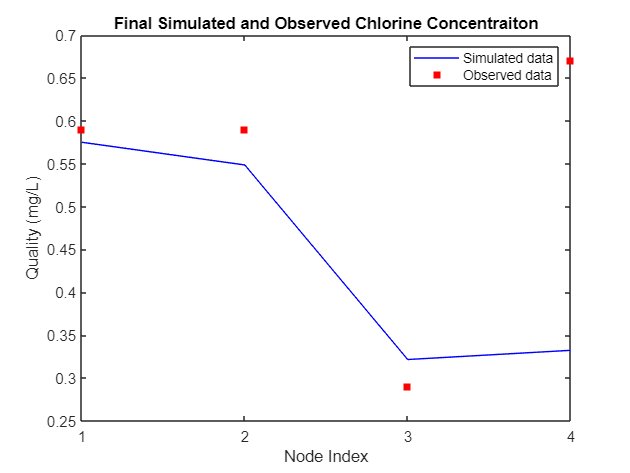


Sim_R_val = c_nodes_Sim_R(:,3*96+1:end);
mse_after_R = mse_function(Sim_R_val,Obs_val);

% Plot the ga-modified quality-time figure
figure,
plot(1:size(c_nodes_Obs,1),Sim_R_val(:,end),'-b')
hold on
scatter(1:size(c_nodes_Obs,1),Obs_val(:,end),'red','filled','square')
legend({'Simulated data','Observed data'})
xlabel('Node Index')
ylabel('Quality (mg/L)')
xticks(1:1:size(c_nodes_Obs,1));
title('Final Simulated and Observed Chlorine Concentraiton')

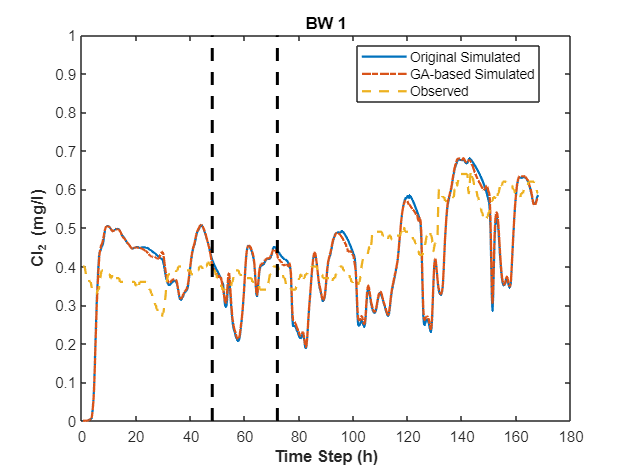

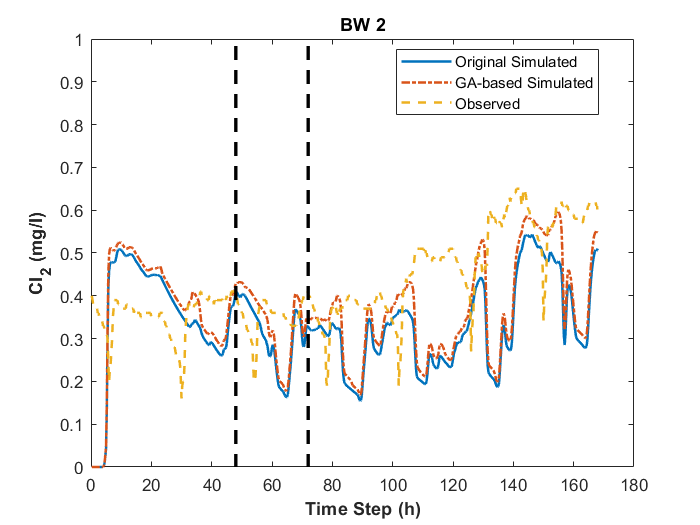

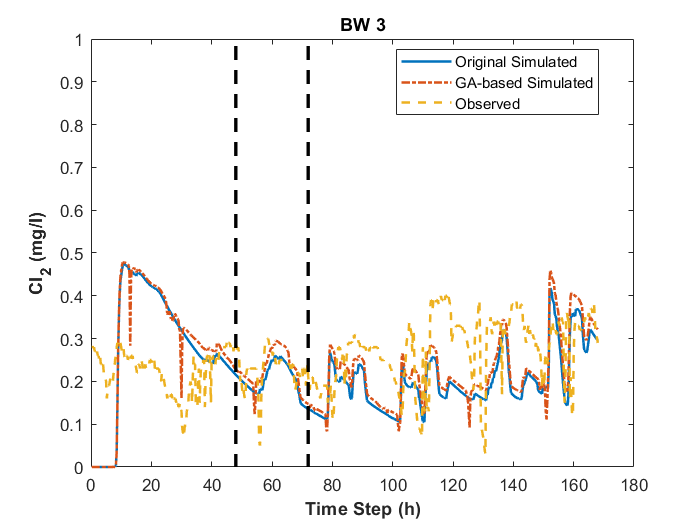

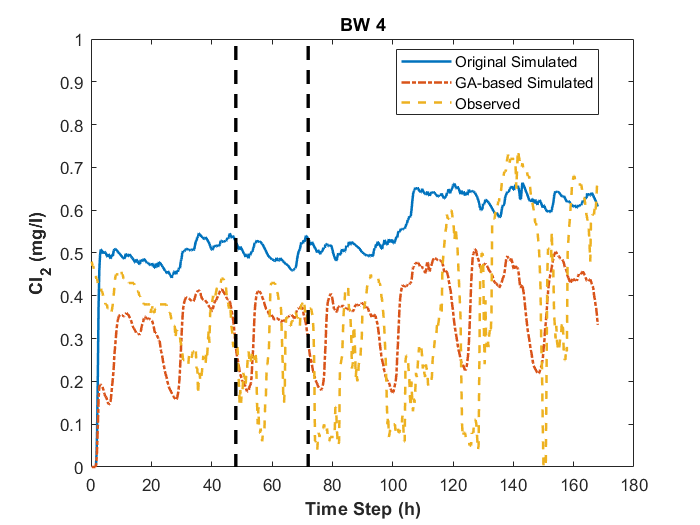

% figures for simulated and observed data
for i = 1:size(c_nodes_Obs,1)
    figure,
    plot(0.25:0.25:days*24,c_nodes_Sim(i,:),'-','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Sim_R(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Obs(i,:),'LineStyle','--','LineWidth',1.5)
    hold on
    plot([48,48],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    hold on
    plot([72,72],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    legend({'Trial-and-Error Simulated','GA-based Simulated','Observed'},'location','best');
    xlabel('Time Step (h)','fontweight','bold')
    ylabel('Cl_2 (mg/l)','fontweight','bold')
    title(Junction_Name{i})
end


fprintf('The mse before calibration is %.4f, after calibration it is %.4f',mse_before,mse_after_R);

The mse before calibration is 0.0386, after calibration it is 0.0247

### Roughness and Diameter based Group Genetic Algorithm Implementation1

Implement genetic algoritnm to solve the parameter optimization problem based on roughness and diameter groups, in this we consider the roughness groups affect the bulk decay and diameter groups affect the wall decay.

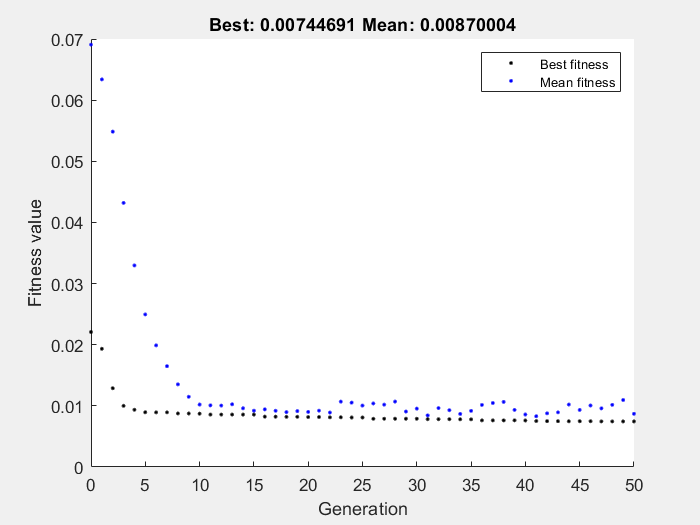

% genetic algorithm implementation
rng default
options = optimoptions('ga','Display','none','PopulationType','DoubleVector','PopulationSize',50, ...
    'Generations',50,"ConstraintTolerance",1e-6,"PlotFcn","gaplotbestf");

lb = -10*ones(15,1);
ub = 0*ones(15,1);

tic;
Mse_function = @(x) Mse_DR(x,Obs_train,Junction_SelectIdx,D,R);
[x_DR, fval_DR] = ga(Mse_function,15,[],[],[],[],lb,ub,[],options);

t_DR = toc;
fprintf('The computation time is %.2fs',t_DR);

The computation time is 590.92s

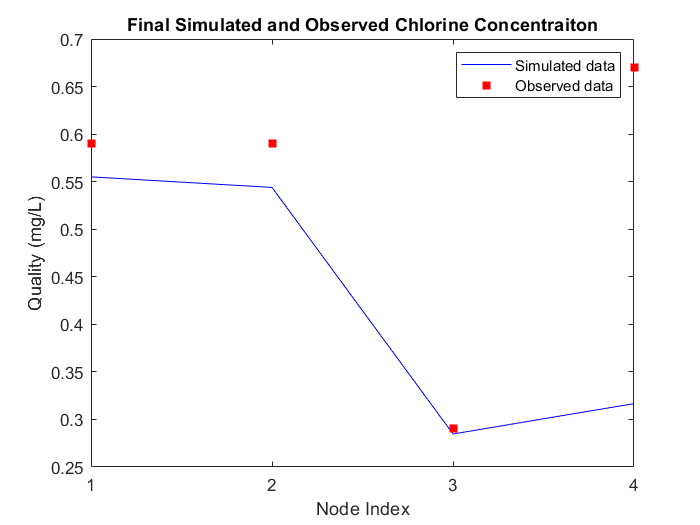


% Test the ga result
thetaR = ones(2281,1); % units of m/day
for i = 1:2281
    if abs(R(i) - 0) <= 0.01
        thetaR(i) = x_DR(1);
    elseif abs(R(i) - 0.1000) <= 0.01
        thetaR(i) = x_DR(2);
    elseif abs(R(i) - 0.1399) <= 0.01
        thetaR(i) = x_DR(3);
    elseif abs(R(i) - 1.5267) <= 0.01
        thetaR(i) = x_DR(4);
    elseif abs(R(i) - 2.1576) <= 0.01
        thetaR(i) = x_DR(5); 
    elseif abs(R(i) - 9.0114) <= 0.01
        thetaR(i) = x_DR(6); 
    elseif abs(R(i) - 10.3677) <= 0.01
        thetaR(i) = x_DR(7); 
    elseif abs(R(i) - 11.6809) <= 0.01
        thetaR(i) = x_DR(8); 
    elseif abs(R(i) - 14.8687) <= 0.01
        thetaR(i) = x_DR(9); 
    elseif abs(R(i) - 16.2377) <= 0.01
        thetaR(i) = x_DR(10); 
    else
        thetaR(i) = x_DR(11);
    end
end

thetaD = ones(2281,1); % units of m/day
for i = 1:2281
    if D(i) <= 75
        thetaD(i) = x_DR(12);
    elseif D(i) > 75 && D(i) <= 150
        thetaD(i) = x_DR(13);
    elseif D(i) > 150 && D(i) <= 250
        thetaD(i) = x_DR(14);
    else
        thetaD(i) = x_DR(15);
    end
end

net.setLinkBulkReactionCoeff(1:np, thetaR);
net.setOptionsPipeBulkReactionOrder(1);
net.setLinkWallReactionCoeff(1:np, thetaD);

quality_res_DR = net.getComputedQualityTimeSeries;
c_nodes_DR = quality_res_DR.NodeQuality';
c_nodes_Sim_DR = c_nodes_DR(Junction_SelectIdx,2:end);

Sim_DR_val = c_nodes_Sim_DR(:,3*96+1:end);
mse_after_DR = mse_function(Sim_DR_val,Obs_val);

% Plot the ga-modified quality-time figure
figure,
plot(1:size(c_nodes_Obs,1),Sim_DR_val(:,end),'-b')
hold on
scatter(1:size(c_nodes_Obs,1),Obs_val(:,end),'red','filled','square')
legend({'Simulated data','Observed data'})
xlabel('Node Index')
ylabel('Quality (mg/L)')
xticks(1:1:size(c_nodes_Obs,1));
title('Final Simulated and Observed Chlorine Concentraiton')

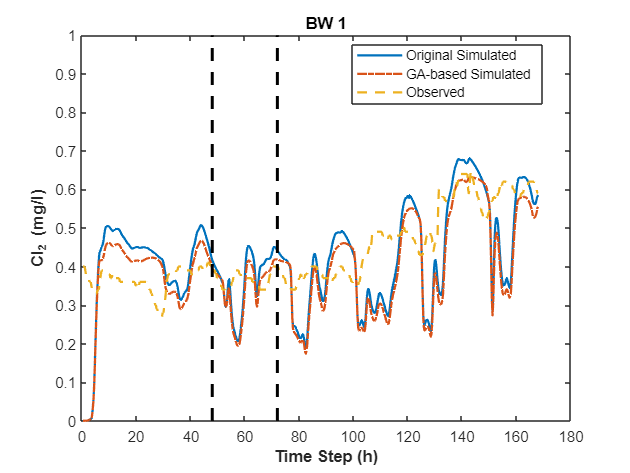

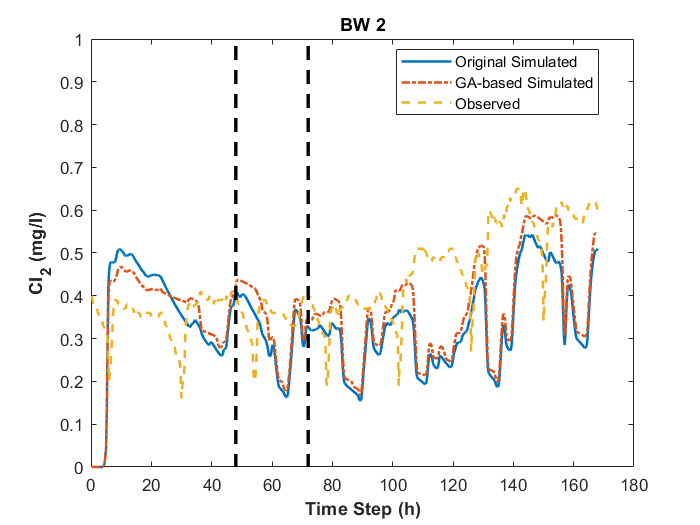

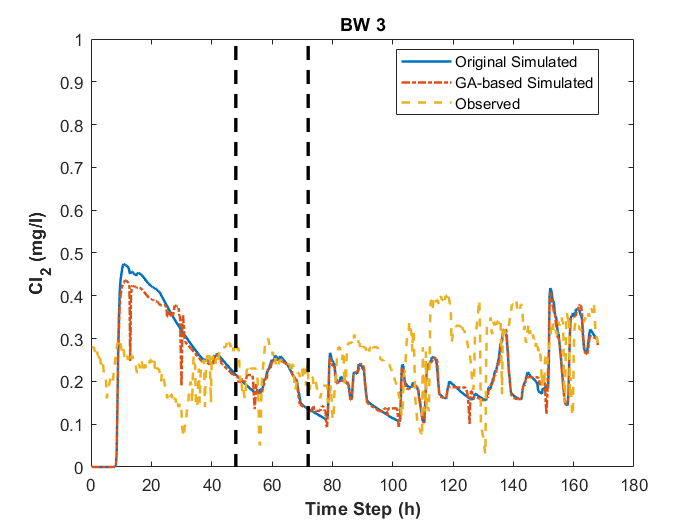

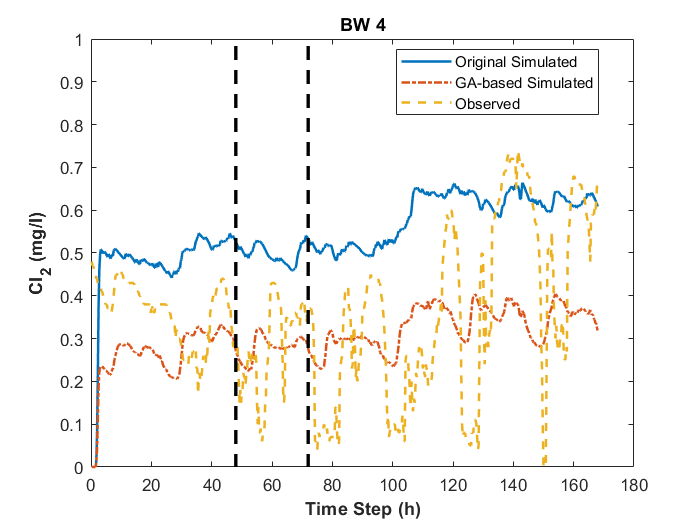

% figures for simulated and observed data
for i = 1:size(c_nodes_Obs,1)
    figure,
    plot(0.25:0.25:days*24,c_nodes_Sim(i,:),'-','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Sim_DR(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Obs(i,:),'LineStyle','--','LineWidth',1.5)
    hold on
    plot([48,48],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    hold on
    plot([72,72],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    legend({'Trial-and-Error Simulated','GA-based Simulated','Observed'},'location','best');
    xlabel('Time Step (h)','fontweight','bold')
    ylabel('Cl_2 (mg/l)','fontweight','bold')
    title(Junction_Name{i})
end


fprintf('The mse before calibration is %.4f, after calibration it is %.4f',mse_before,mse_after_DR);

The mse before calibration is 0.0386, after calibration it is 0.0261

### Roughness and Diameter based Group Genetic Algorithm Implementation2

Implement genetic algoritnm to solve the parameter optimization problem based on roughness and diameter groups, in this we consider the roughness groups and diameter groups affect the bulk decay together.

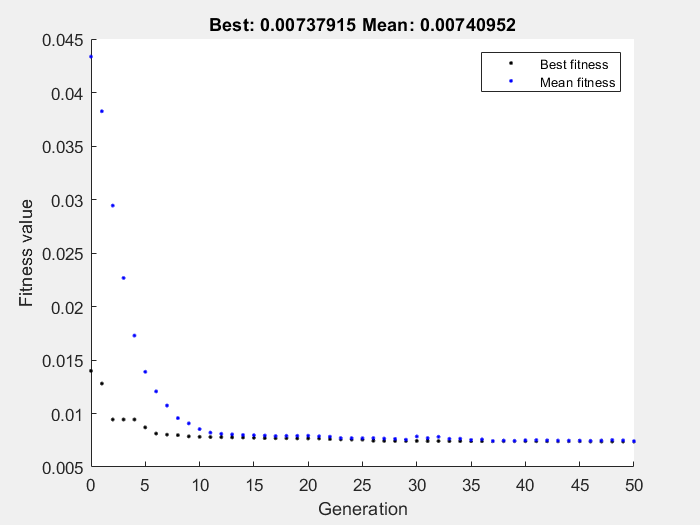

% genetic algorithm implementation
rng default
options = optimoptions('ga','Display','none','PopulationType','DoubleVector','PopulationSize',50, ...
    'Generations',50,"ConstraintTolerance",1e-6,"PlotFcn","gaplotbestf");

lb = -10*ones(22,1);
ub = 0*ones(22,1);

tic;
Mse_function = @(x) Mse_DandR(x,Obs_train,Junction_SelectIdx,D,R);
[x_DandR, fval_DandR] = ga(Mse_function,22,[],[],[],[],lb,ub,[],options);

t_DandR = toc;
fprintf('The computation time is %.2fs',t_DandR);

The computation time is 547.50s

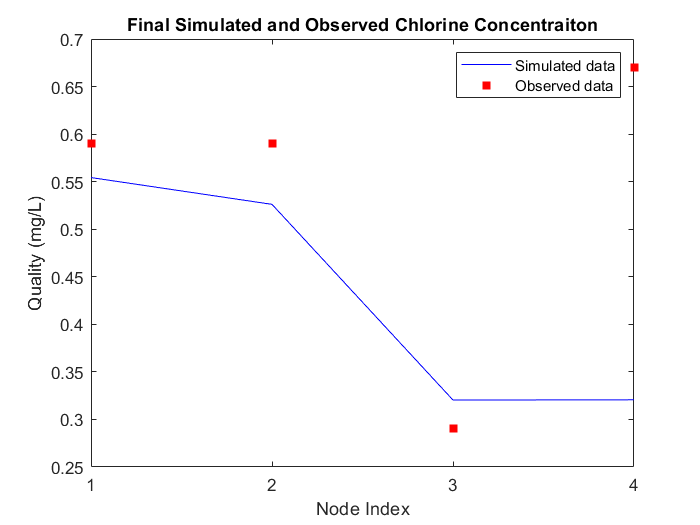


% Test the ga result
thetaDandR = ones(2281,1); % units of m/day
for i = 1:2281
    if abs(R(i) - 0) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(1);
        else
            thetaDandR(i) = x_DandR(2);
        end
    elseif abs(R(i) - 0.1000) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(3);
        else
            thetaDandR(i) = x_DandR(4);
        end
    elseif abs(R(i) - 0.1399) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(5);
        else
            thetaDandR(i) = x_DandR(6);
        end
    elseif abs(R(i) - 1.5267) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(7);
        else
            thetaDandR(i) = x_DandR(8);
        end
    elseif abs(R(i) - 2.1576) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(9);
        else
            thetaDandR(i) = x_DandR(10);
        end
    elseif abs(R(i) - 9.0114) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(11);
        else
            thetaDandR(i) = x_DandR(12);
        end
    elseif abs(R(i) - 10.3677) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(13);
        else
            thetaDandR(i) = x_DandR(14);
        end
    elseif abs(R(i) - 11.6809) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(15);
        else
            thetaDandR(i) = x_DandR(16);
        end
    elseif abs(R(i) - 14.8687) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(17);
        else
            thetaDandR(i) = x_DandR(18);
        end 
    elseif abs(R(i) - 16.2377) <= 0.01
        if D(i) <= 150
            thetaDandR(i) = x_DandR(19);
        else
            thetaDandR(i) = x_DandR(20);
        end
    else
        if D(i) <= 150
            thetaDandR(i) = x_DandR(21);
        else
            thetaDandR(i) = x_DandR(22);
        end
    end
end

net.setLinkBulkReactionCoeff(1:np, thetaDandR);
net.setOptionsPipeBulkReactionOrder(1);

quality_res_DandR = net.getComputedQualityTimeSeries;
c_nodes_DandR = quality_res_DandR.NodeQuality';
c_nodes_Sim_DandR = c_nodes_DandR(Junction_SelectIdx,2:end);

Sim_DandR_val = c_nodes_Sim_DandR(:,3*96+1:end);
mse_after_DandR = mse_function(Sim_DandR_val,Obs_val);

% Plot the ga-modified quality-time figure
figure,
plot(1:size(c_nodes_Obs,1),Sim_DandR_val(:,end),'-b')
hold on
scatter(1:size(c_nodes_Obs,1),Obs_val(:,end),'red','filled','square')
legend({'Simulated data','Observed data'})
xlabel('Node Index')
ylabel('Quality (mg/L)')
xticks(1:1:size(c_nodes_Obs,1));
title('Final Simulated and Observed Chlorine Concentraiton')

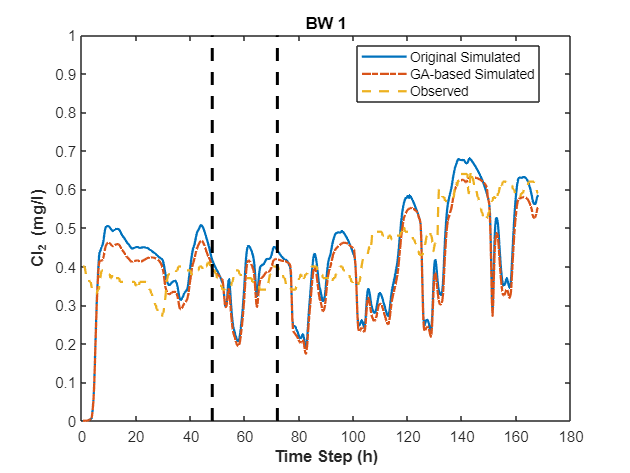

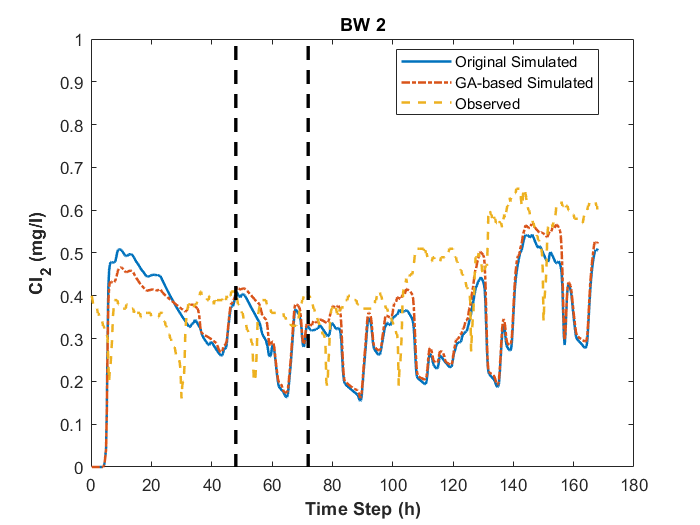

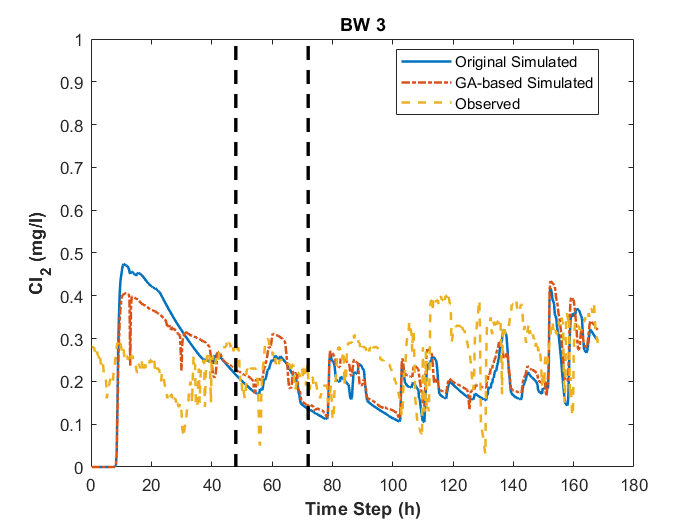

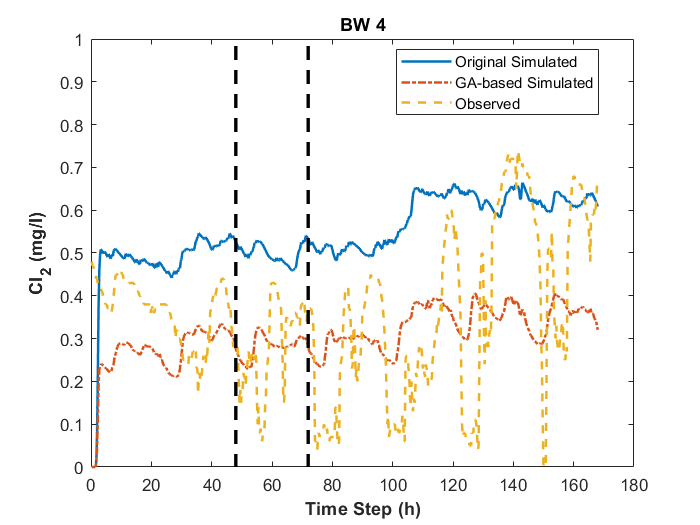


% figures for simulated and observed data
for i = 1:size(c_nodes_Obs,1)
    figure,
    plot(0.25:0.25:days*24,c_nodes_Sim(i,:),'-','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Sim_DandR(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Obs(i,:),'LineStyle','--','LineWidth',1.5)
    hold on
    plot([48,48],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    hold on
    plot([72,72],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    legend({'Trial-and-Error Simulated','GA-based Simulated','Observed'},'location','best');
    xlabel('Time Step (h)','fontweight','bold')
    ylabel('Cl_2 (mg/l)','fontweight','bold')
    title(Junction_Name{i})
end

fprintf('The mse before calibration is %.4f, after calibration it is %.4f',mse_before,mse_after_DandR);

The mse before calibration is 0.0386, after calibration it is 0.0262

### Test the hydrants

Find out the regulations in the node with hydrants.

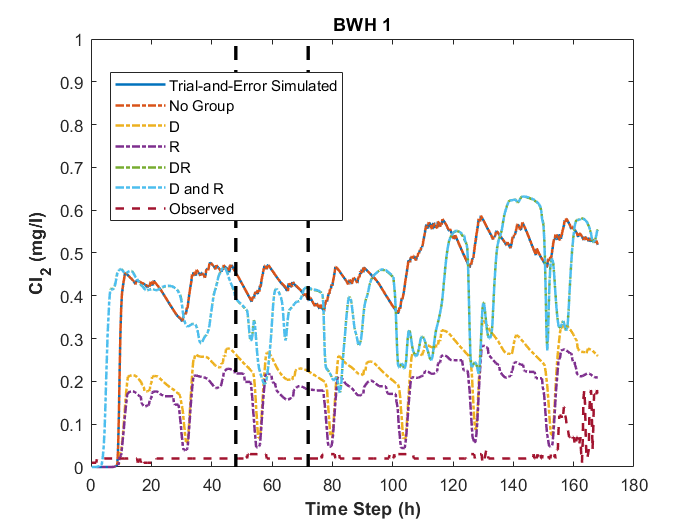

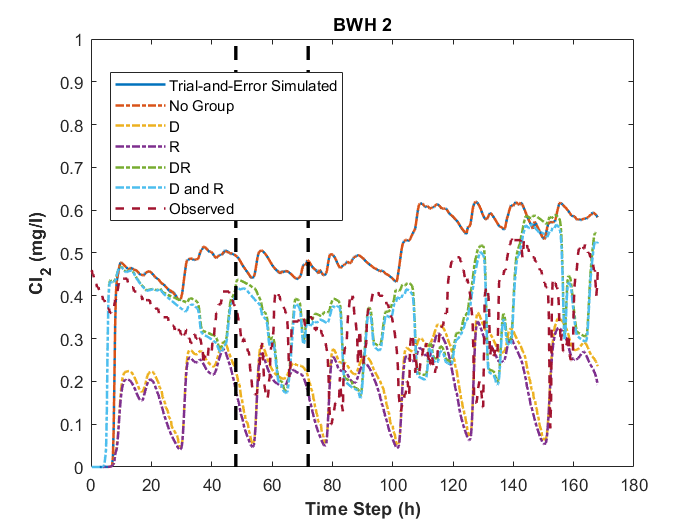

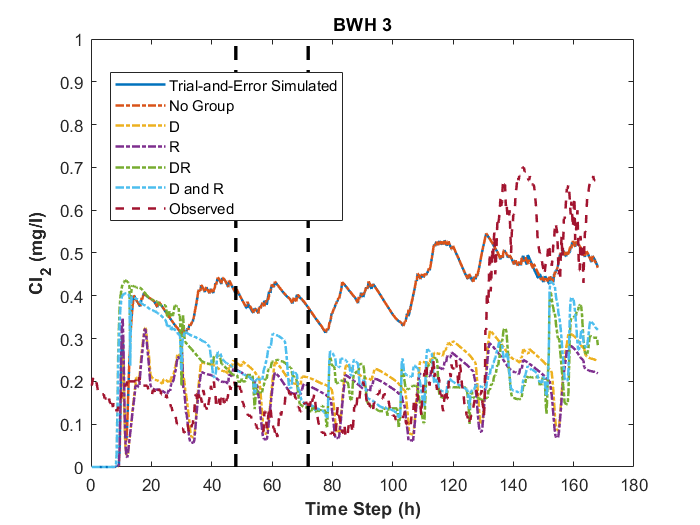

% Hydrant node chlorine concentration, DR based group as an example
c_nodes_hydrantObs = wq_data.chlorine([2,5,8],:);
c_nodes_hydrantSim = c_nodes(Junction_HydrantIdx,2:end);
c_nodes_hydrant_Sim_NoGroup = c_nodes_NoGroup(Junction_HydrantIdx,2:end);
c_nodes_hydrant_Sim_D = c_nodes_D(Junction_HydrantIdx,2:end);
c_nodes_hydrant_Sim_R = c_nodes_R(Junction_HydrantIdx,2:end);
c_nodes_hydrant_Sim_DR = c_nodes_DR(Junction_HydrantIdx,2:end);
c_nodes_hydrant_Sim_DandR = c_nodes_DandR(Junction_HydrantIdx,2:end);

% Plot figure for visualization
for i = 1:size(c_nodes_hydrantObs,1)
    figure,
    plot(0.25:0.25:days*24,c_nodes_hydrantSim(i,:),'-','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_hydrant_Sim_NoGroup(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_hydrant_Sim_D(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_hydrant_Sim_R(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Sim_DR(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_Sim_DandR(i,:),'LineStyle','-.','LineWidth',1.5)
    hold on
    plot(0.25:0.25:days*24,c_nodes_hydrantObs(i,:),'LineStyle','--','LineWidth',1.5)
    hold on
    plot([48,48],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    hold on
    plot([72,72],[0,1],'Color','k','LineStyle','--','LineWidth',2)
    legend({'Trial-and-Error Simulated','No Group','D','R','DR','D and R','Observed'},'location','best');
    xlabel('Time Step (h)','fontweight','bold')
    ylabel('Cl_2 (mg/l)','fontweight','bold')
    title(Junction_Hydrant_Name{i})
end

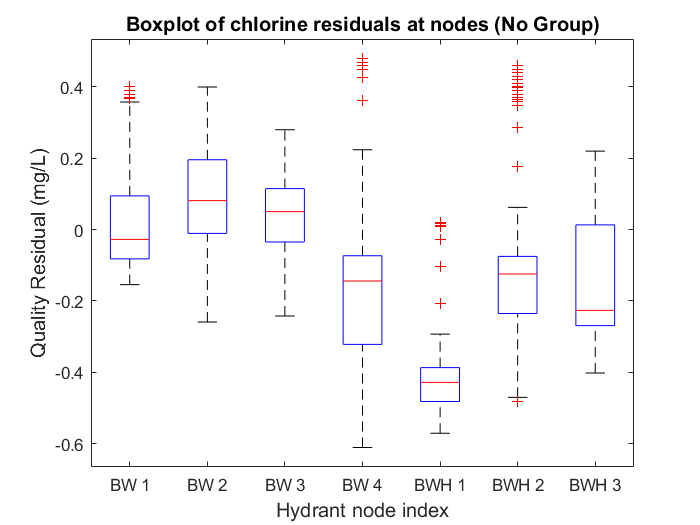

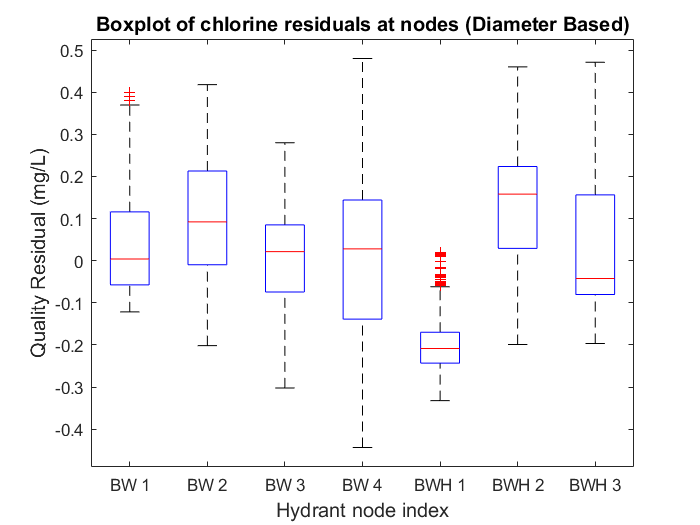

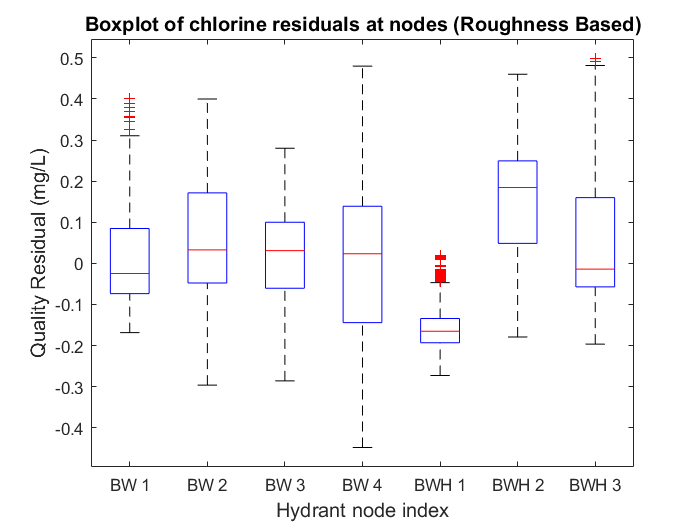

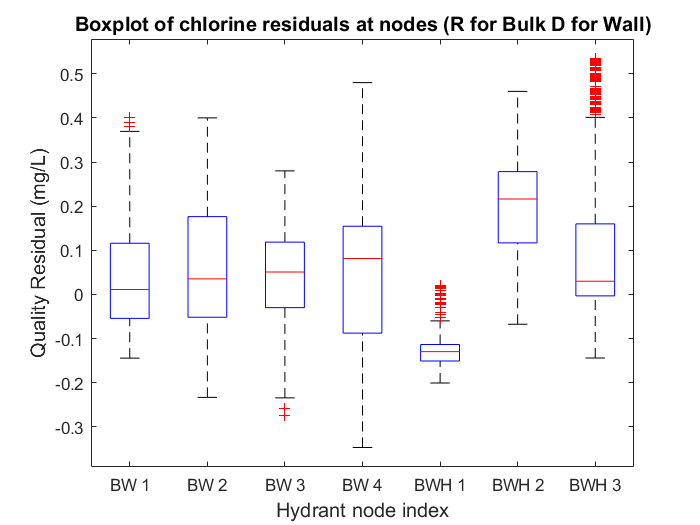

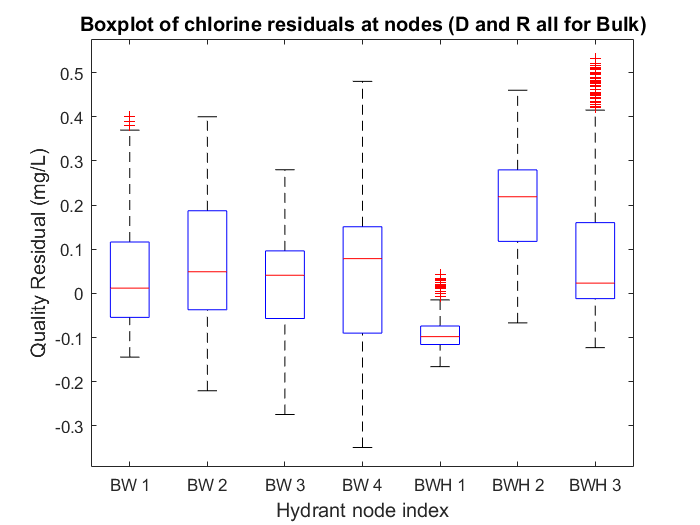

% Boxplot to see the residual at BWH
c_nodes_hydrant_NoGroup_Residual = c_nodes_hydrantObs - c_nodes_hydrant_Sim_NoGroup;
c_nodes_hydrant_NoGroup_Residual = c_nodes_hydrant_NoGroup_Residual';

c_nodes_hydrant_D_Residual = c_nodes_hydrantObs - c_nodes_hydrant_Sim_D;
c_nodes_hydrant_D_Residual = c_nodes_hydrant_D_Residual';

c_nodes_hydrant_R_Residual = c_nodes_hydrantObs - c_nodes_hydrant_Sim_R;
c_nodes_hydrant_R_Residual = c_nodes_hydrant_R_Residual';

c_nodes_hydrant_DR_Residual = c_nodes_hydrantObs - c_nodes_hydrant_Sim_DR;
c_nodes_hydrant_DR_Residual = c_nodes_hydrant_DR_Residual';

c_nodes_hydrant_DandR_Residual = c_nodes_hydrantObs - c_nodes_hydrant_Sim_DandR;
c_nodes_hydrant_DandR_Residual = c_nodes_hydrant_DandR_Residual';

c_nodes_hydrant_Residual = {c_nodes_hydrant_NoGroup_Residual,c_nodes_hydrant_D_Residual,...
    c_nodes_hydrant_R_Residual,c_nodes_hydrant_DR_Residual,c_nodes_hydrant_DandR_Residual};

% Calculate the residuals at BW nodes.
c_nodes_NoGroup_Residual = c_nodes_Obs - c_nodes_NoGroup(Junction_SelectIdx,2:end);
c_nodes_NoGroup_Residual = c_nodes_NoGroup_Residual';
c_nodes_D_Residual = c_nodes_Obs - c_nodes_D(Junction_SelectIdx,2:end);
c_nodes_D_Residual = c_nodes_D_Residual';
c_nodes_R_Residual = c_nodes_Obs - c_nodes_R(Junction_SelectIdx,2:end);
c_nodes_R_Residual = c_nodes_R_Residual';
c_nodes_DR_Residual = c_nodes_Obs - c_nodes_DR(Junction_SelectIdx,2:end);
c_nodes_DR_Residual = c_nodes_DR_Residual';
c_nodes_DandR_Residual = c_nodes_Obs - c_nodes_DandR(Junction_SelectIdx,2:end);
c_nodes_DandR_Residual = c_nodes_DandR_Residual';

c_nodes_Residual = {[c_nodes_NoGroup_Residual,c_nodes_hydrant_NoGroup_Residual],...
    [c_nodes_D_Residual,c_nodes_hydrant_D_Residual],...
    [c_nodes_R_Residual,c_nodes_hydrant_R_Residual],...
    [c_nodes_DR_Residual,c_nodes_hydrant_DR_Residual],...
    [c_nodes_DandR_Residual,c_nodes_hydrant_DandR_Residual]};
BoxPlot_Name = {'(No Group)','(Diameter Based)','(Roughness Based)','(R for Bulk D for Wall)',...
    '(D and R all for Bulk)'};


for i = 1:length(BoxPlot_Name)
    figure,
    boxplot(c_nodes_Residual{i});
    xlabel('Hydrant node index','FontSize',12)
    ylabel('Quality Residual (mg/L)','FontSize',12)
    title(['Boxplot of chlorine residuals at nodes ',BoxPlot_Name{i}],'FontSize',12)
    xticklabels([Junction_Name,Junction_Hydrant_Name]);
end